clc
clear all
close all
load("lin_disc_7071.mat");

Ts = 0.02;

ss_d = c2d(ss_c,Ts,'zoh');
A = ss_d.A;
B = ss_d.B;
C = ss_d.C;
D = ss_d.D;

# **MPC**

[dx, du] = size(B);
dy = size(C,1);

x0 = [0 0 0 0]';
u0 = zeros(2,1);

umin = -24;
umax = 24;
delta_u_min = -5;
delta_u_max = 5;
theta_min = -0.89;
theta_max = 0.89;

Q = Ts*diag([1e4 1e3 10 50]);
R = Ts*1e-1*eye(2);
P = 1e2*Q;

Npred = 200;
Nsim = 1500;

% xref = [-deg2rad(20) deg2rad(45) 0 0]';

% phi = 5*pi/6;

% % Parametrii cercului
% R_c = 3;                % Raza cercului
omega_1 = 2 * pi * 0.05;
omega_2 = 2 * pi * 0.04; % Viteza unghiulară (face un cerc complet la 400 de pași)
% 
% % Timpul extins pentru a acoperi și orizontul de predicție de la final
t = Ts*(1:(Nsim + Npred)); 
% 
% % Inițializăm matricea de referință
xref = zeros(dx, length(t));
% 
% % Pozițiile (x1 și x2) pe un cerc
xref(1, :) = -deg2rad(20)*sign(sin(omega_1 * t)); 
xref(2, :) = -deg2rad(45)*sign(sin(omega_2 * t)); 
% 
% % Vitezele (x3 și x4)
% % Viteza este derivata poziției. E bine să le dăm controllerului
% % ca referință pentru a urmări mișcarea cât mai fluid.
% xref(3, :) = -R_c * omega * sin(omega * t + phi).*double(t>=300); 
% xref(4, :) =  R_c * omega * cos(omega * t).*double(t>=300);

import casadi.*

solver = casadi.Opti();
x = solver.variable(dx, Npred+1);
u = solver.variable(du, Npred);
xinit = solver.parameter(dx, 1);
uinit = solver.parameter(du, 1);
xref_param = solver.parameter(dx, Npred+1);

solver.subject_to(x(:,1)==xinit)
for k = 1:Npred
    solver.subject_to(x(: ,k+1) == A*x(: ,k) + B*u(: ,k))
    solver.subject_to(umin <= u(:, k) <= umax)
    solver.subject_to(theta_min <= x(1,k) <= theta_max)

    if k == 1
        solver.subject_to(delta_u_min <= u(:,k) - uinit <= delta_u_max)
    else
        solver.subject_to(delta_u_min <= u(:,k) - u(:,k-1) <= delta_u_max)
    end
end

objective = 0;
for k = 1:Npred
    objective = objective + (x(:,k)-xref_param(:,k))'*Q*(x(:,k)-xref_param(:,k));
    if k == 1
        objective = objective + (u(:,k)-uinit)'*R*(u(:,k)-uinit);
    else
        objective = objective + (u(:,k)-u(:,k-1))'*R*(u(:,k)-u(:,k-1));
    end
end
objective = objective + (x(:, Npred+1)-xref_param(:, Npred+1))'*P*(x(:, Npred+1)-xref_param(:, Npred+1));
solver.minimize(objective)

options.ipopt.print_level = 0;
options.ipopt.sb = 'yes';
options.print_time = 0;
solver.solver('ipopt', options)

usim = zeros(du, Nsim);
ysim = zeros(dy, Nsim);
xsim = zeros(dx, Nsim + 1);
xsim(:,1) = x0;
usim_init = u0;

timer = tic;
for i = 1:Nsim
    solver.set_value(xinit, xsim(:, i))
    solver.set_value(uinit, usim_init)
    
    % % Fără if/else! Extragem direct fereastra necesară.
    current_xref = xref(:, i : i + Npred);
    solver.set_value(xref_param, current_xref);

    sol = solver.solve();
    usol = sol.value(u);
    usim_init = usol(:,1);
    usim(:, i) = usol(:,1);
    xsim(:, i + 1) = A*xsim(:, i) + B*usim(:, i);
    ysim(:, i) = C*xsim(:,i) + D*usim(:,i);
end
time_CasAdi = toc(timer)

time_CasAdi = 438.8093

% save("mpc_track_sim_20.mat","time_CasAdi", "usim", "xsim", "Nsim", "theta_max", "theta_min", "umin", "umax","Ts","xref")

% figure
% plot(ysim(1,:),ysim(2,:),xref(1),xref(2),'*');
% 
% grid on
% title('state space');
% xlabel('$x_1$','Interpreter','latex')
% ylabel('$x_2$','Interpreter','latex')
% set(gcf, 'Visible','on')

% % Corectura calcul eroare
% error = sqrt((xsim(1, :) - xref(1,:)).^2 + (xsim(2, :) - xref(2,:)).^2 + (xsim(3, :)-xref(3,:)).^2 + (xsim(4, :)-xref(4)).^2);
% Avg_error = mean(error)
% Avg_u1 = mean(abs(usim(1,:)))
% Avg_u2 = mean(abs(usim(2,:)))

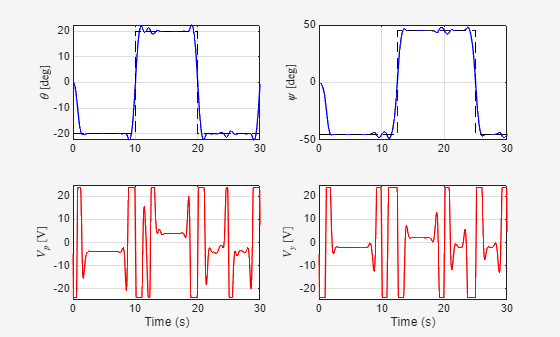

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


fig = figure;
subplot(2,2,1)
plot(Ts*(1:Nsim), 180/pi*xsim(1,1:Nsim),'b-',Ts*(1:Nsim), 180/pi*xref(1,1:Nsim),'k--');
hold on 
grid on
% plot(Ts*(1:Nsim), -20*ones(Nsim), 'k-.');
% plot(Ts*(1:Nsim), 180/pi*theta_min*ones(Nsim), 'k:',Ts*(1:Nsim), 180/pi*theta_max*ones(Nsim), 'k:')
xlim([0 30]);
ylabel(['$\theta$' ' [deg]'], 'Interpreter','latex');
subplot(2,2,3)
plot(Ts*(1:Nsim), usim(1,:),'r-');
grid on
hold on
% plot(Ts*(1:Nsim), umin*ones(Nsim), 'k:',Ts*(1:Nsim), umax*ones(Nsim), 'k:');
xlim([0 30]);
ylim([-25 25]);
ylabel(['$V_p$' ' [V]'], 'Interpreter','latex');
xlabel('Time (s)')

subplot(2,2,2)
plot(Ts*(1:Nsim), 180/pi*xsim(2,1:Nsim),'b-',Ts*(1:Nsim),180/pi*xref(2,1:Nsim),'k--');
hold on 
grid on
% plot(Ts*(1:Nsim), 45*ones(Nsim), 'k-.');
xlim([0 30]);
ylabel(['$\psi$' ' [deg]'],'Interpreter','latex');
subplot(2,2,4)
plot(Ts*(1:Nsim), usim(2,:),'r-');
grid on
hold on
% plot(Ts*(1:Nsim), umin*ones(Nsim), 'k:',Ts*(1:Nsim), umax*ones(Nsim), 'k:');
xlim([0 30]);
ylim([-25 25]);
ylabel(['$V_y$' ' [V]'], 'Interpreter','latex');
xlabel('Time (s)')
set(gcf, 'visible', 'on')
cleanfigure;
matlab2tikz('MPCtrack_sim_200.tex','width','\textwidth');

save("mpc_track_sim_200.mat","time_CasAdi", "usim", "xsim", "Nsim", "theta_max", "theta_min", "umin", "umax","Ts","xref")